# 三维绘图之曲线、曲面和散点图

- 三维曲线 plot3

- 散点图 scatter3

- 三维曲面 mesh、surf

## 三维曲线

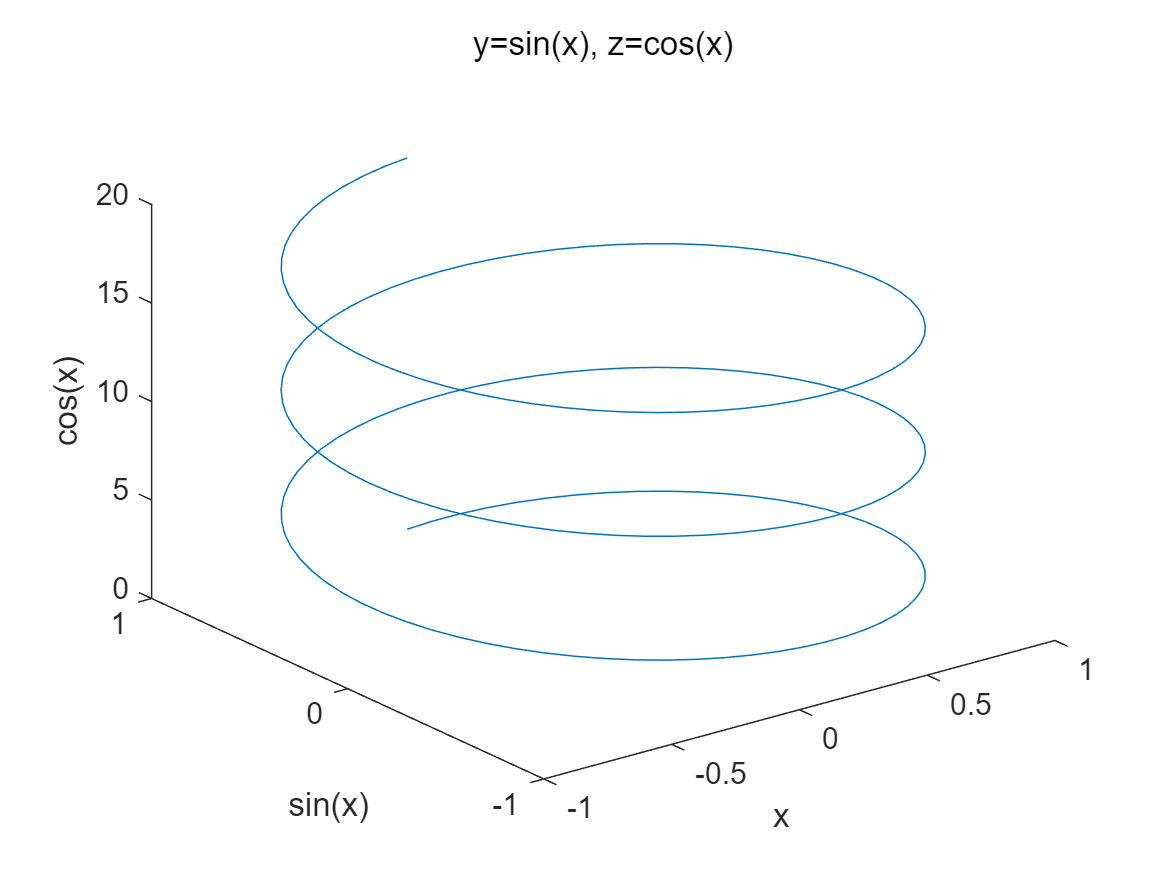

% plot3(X1, Y1, Z1, Linespec1, ... , Xn, Yn, Zn, Linespecn)

x = linspace(0, 6*pi, 200);
y = sin(x);
z = cos(x);

plot3(y, z, x);
xlabel('x');
ylabel('sin(x)');
zlabel('cos(x)');
title('y=sin(x), z=cos(x)');

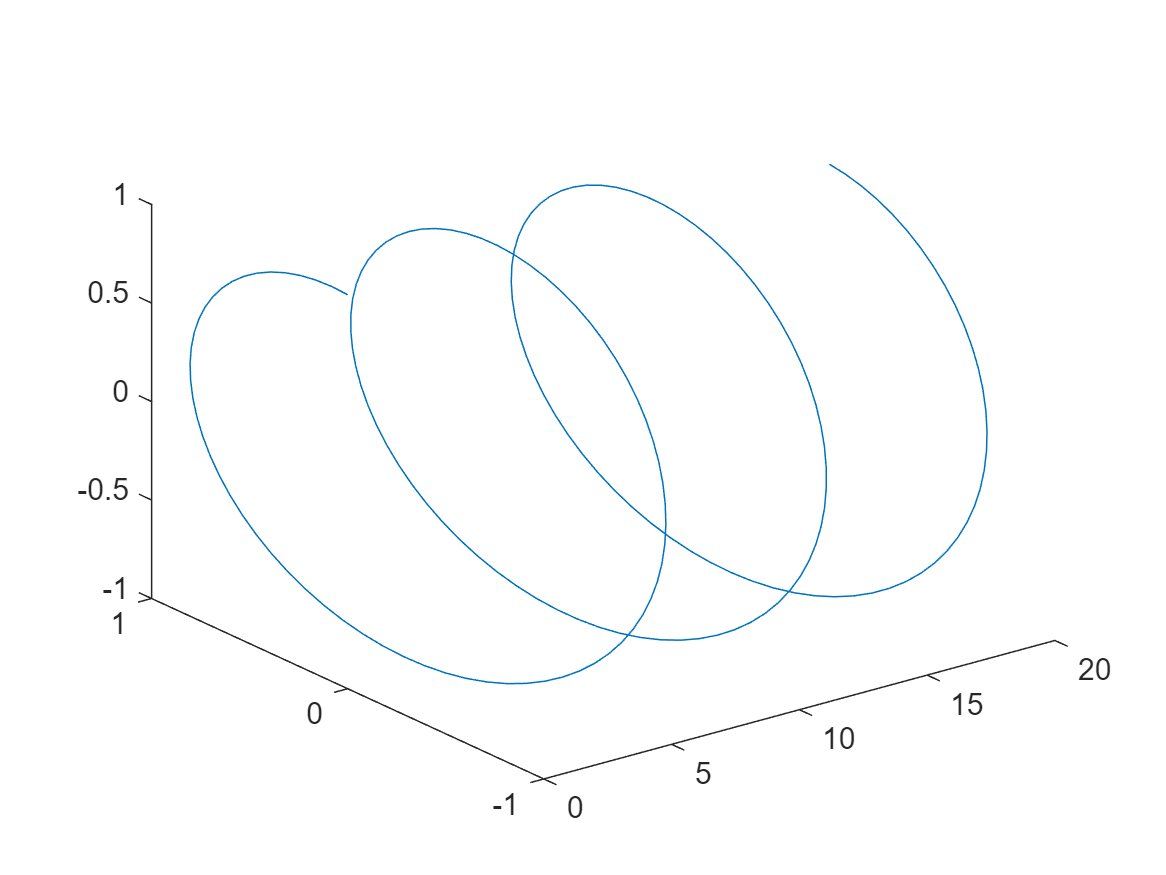

plot3(x, y, z);

## 三维散点图

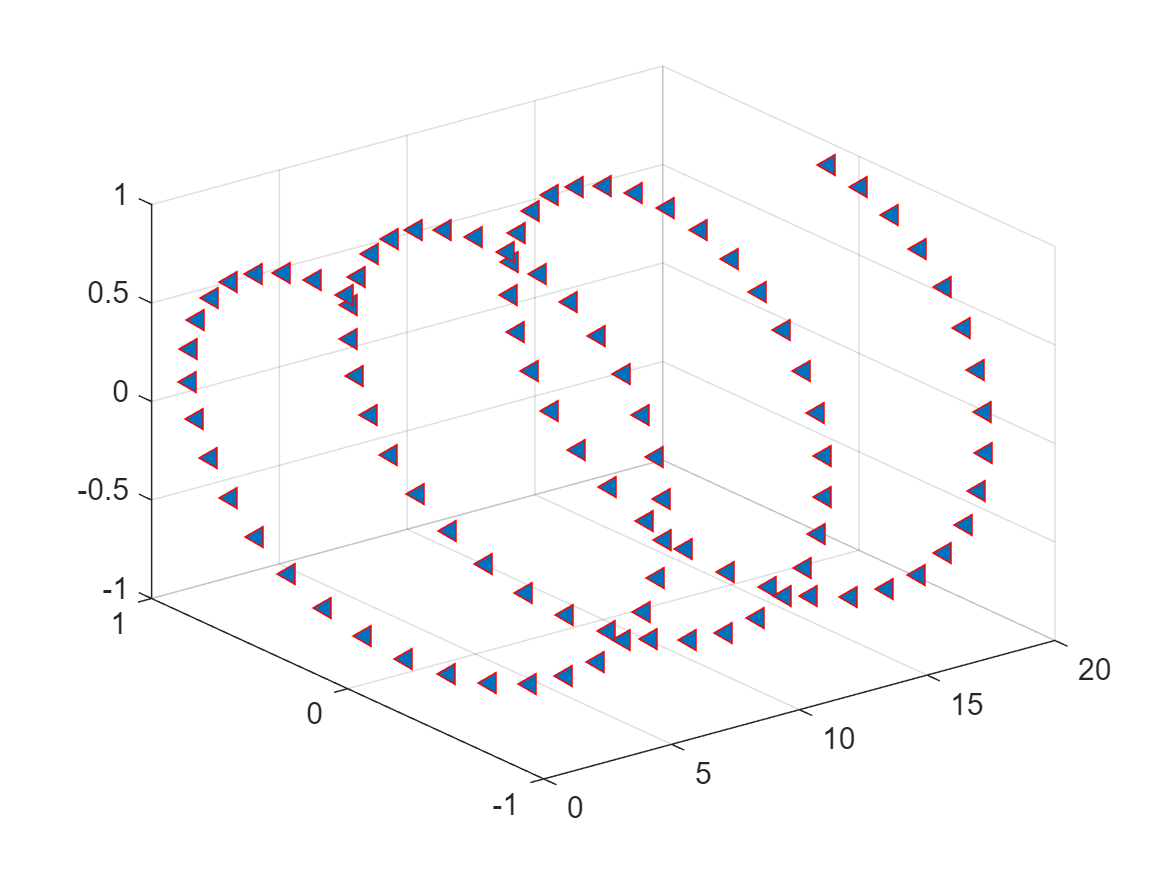

x = linspace(0, 6*pi, 100);
y = sin(x);
z = cos(x);

scatter3(x, y, z, '<', "filled", "MarkerEdgeColor", 'r');

## 三维曲面

x = 1:3;
y = 1:5;
[X, Y] = meshgrid(x, y)

X =      1     2     3
     1     2     3
     1     2     3
     1     2     3
     1     2     3


Y =      1     1     1
     2     2     2
     3     3     3
     4     4     4
     5     5     5


### 绘制$z=xe^{-\left(x^2 +y^2 \right)}$

[x, y] = meshgrid(-10:0.5:10, -10:0.5:10)

x =   -10.0000   -9.5000   -9.0000   -8.5000   -8.0000   -7.5000   -7.0000   -6.5000   -6.0000   -5.5000   -5.0000   -4.5000   -4.0000   -3.5000   -3.0000   -2.5000   -2.0000   -1.5000   -1.0000   -0.5000         0    0.5000    1.0000    1.5000    2.0000    2.5000    3.0000    3.5000    4.0000    4.5000    5.0000    5.5000    6.0000    6.5000    7.0000    7.5000    8.0000    8.5000    9.0000    9.5000   10.0000
  -10.0000   -9.5000   -9.0000   -8.5000   -8.0000   -7.5000   -7.0000   -6.5000   -6.0000   -5.5000   -5.0000   -4.5000   -4.0000   -3.5000   -3.0000   -2.5000   -2.0000   -1.5000   -1.0000   -0.5000         0    0.5000    1.0000    1.5000    2.0000    2.5000    3.0000    3.5000    4.0000    4.5000    5.0000    5.5000    6.0000    6.5000    7.0000    7.5000    8.0000    8.5000    9.0000    9.5000   10.0000
  -10.0000   -9.5000   -9.0000   -8.5000   -8.0000   -7.5000   -7.0000   -6.5000   -6.0000   -5.5000   -5.0000   -4.5000   -4.0000   -3.5000   -3.0000   -2.5000   -2.0000   -

y =   -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000
   -9.5000   -9.5000   -9.5000   -9.5000   -9.5000   -9.5000   -9.5000   -9.5000   -9.5000   -9.5000   -9.5000   -9.5000   -9.5000   -9.5000   -9.5000   -9.5000   -9.5000   -9.5000   -9.5000   -9.5000   -9.5000   -9.5000   -9.5000   -9.5000   -9.5000   -9.5000   -9.5000   -9.5000   -9.5000   -9.5000   -9.5000   -9.5000   -9.5000   -9.5000   -9.5000   -9.5000   -9.5000   -9.5000   -9.5000   -9.5000   -9.5000
   -9.0000   -9.0000   -9.0000   -9.0000   -9.0000   -9.0000   -9.0000   -9.0000   -9.0000   -9.0000   -9.0000   -9.0000   -9.0000   -9.0000   -9.0000   -9.0000   -9.0000   -

z = x.*exp(-x.^2-y.^2)

z =    -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -

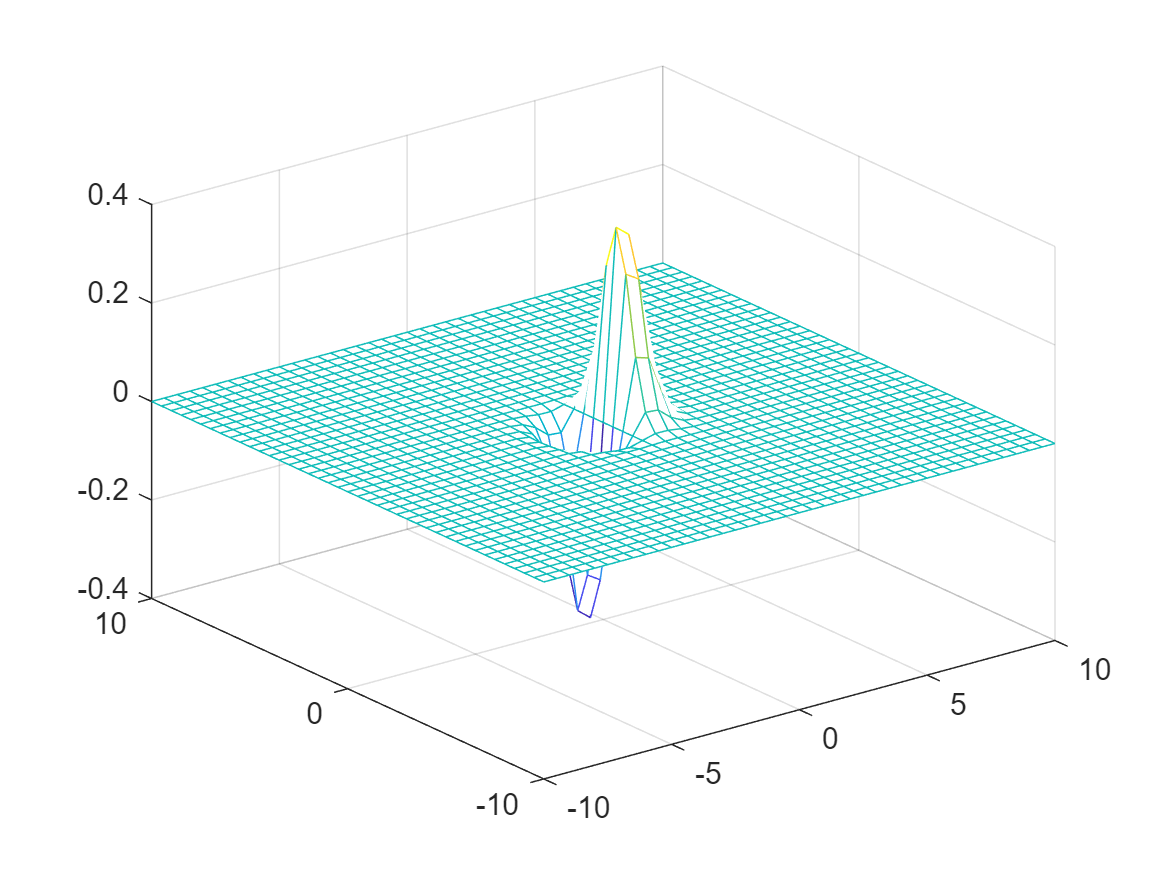

mesh(x, y, z)

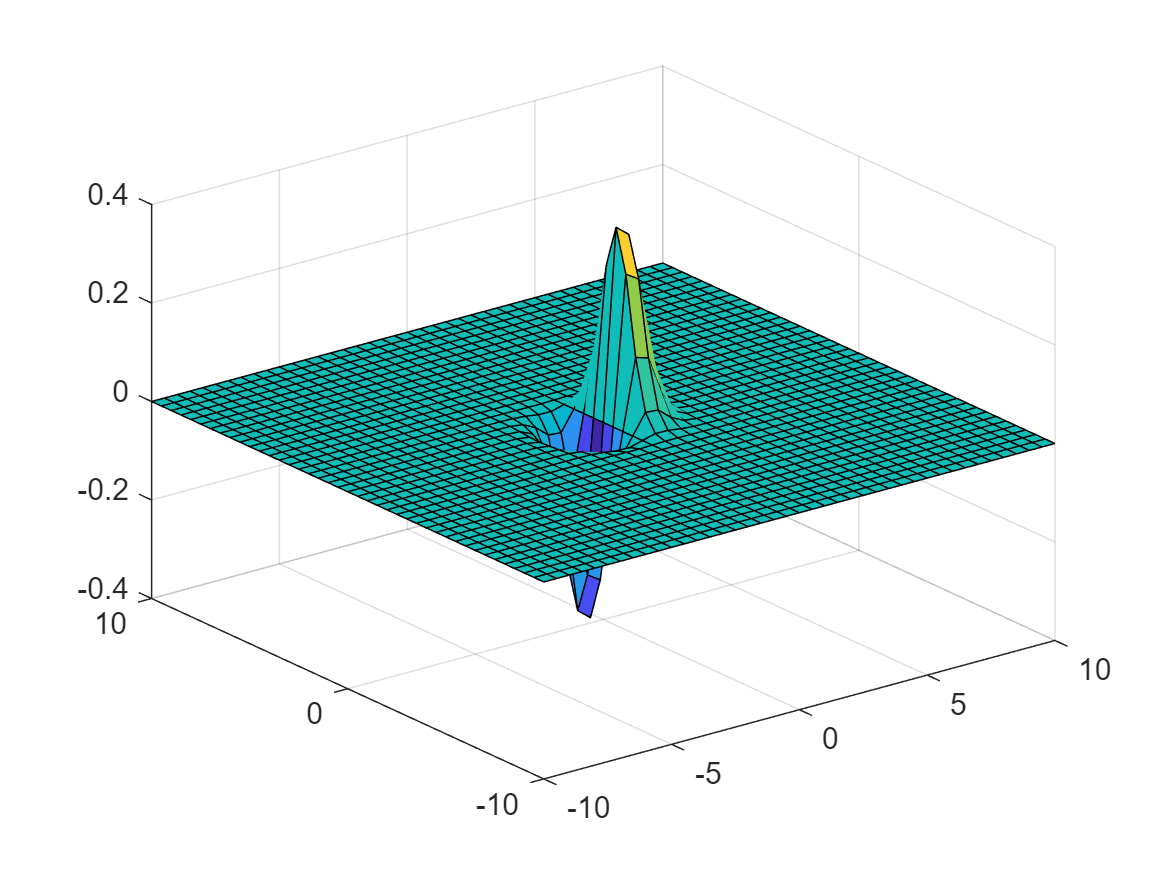

surf(x, y, z)